Задание 1.

p1 = [0; 0];
p2 = [-1; 1];
p3 = [-1; 0];
p4 = [1; 1];
t1 = [0];
t2 = [1];
t3 = [1];
t4 = [0];

net = newp([-2 2; -2 2], 1);
net.b{1} = [-0.5];
w = [0.5 0.5];
net.IW{1, 1} = w;

a = sim(net, p1)

a = 0

a = sim(net, p2)

a = 0

e = t2 - a;
dw = learnp(w, p2, [], [], [], [], e, [], [], [], [], []);
w = w + dw

w =    -0.5000    1.5000


net.IW{1, 1} = w;
a = sim(net, p2)

a = 1

a = sim(net, p3)

a = 1

a = sim(net, p4)

a = 1

e = t4 - a;
dw = learnp(w, p4, [], [], [], [], e, [], [], [], [], []);
w = w + dw

w =    -1.5000    0.5000


net.IW{1, 1} = w;
a = sim(net, p4)

a = 0

a = sim(net, p1)

a = 0

a = sim(net, p2)

a = 1

a = sim(net, p3)

a = 1

a = sim(net, p4)

a = 0

num_points = 10;
ginput_point_value = 1;
figure;
grid on;
xlim manual;
ylim manual;
xlim([-3 3]);
ylim([-3 3]);
hold on;
for cycle_step = 1:num_points
    [x_current, y_current] = ginput(ginput_point_value);
    a = sim(net, [x_current; y_current]);
    if (a == 1)
        scatter(x_current, y_current, 'filled', 'r');
    else
        scatter(x_current, y_current, 'filled', 'g');
    end
end

Error using ginput
Interrupted by figure deletion

Задание 2.

x = rand(1, 3);
y = rand(1, 3);
z = rand(1, 3);

v1 = y - x;
v2 = z - x;

n = cross(v1, v2);

n = n / norm(n);

A = n(1);
B = n(2);
C = n(3);

D = -(A * 0.5 + B * 0.5 + C * 0.5);

net = newp([-5 5; -5 5; -5 5], 1);
net.b{1} = [D];
w = [A B C];
net.IW{1, 1} = w;

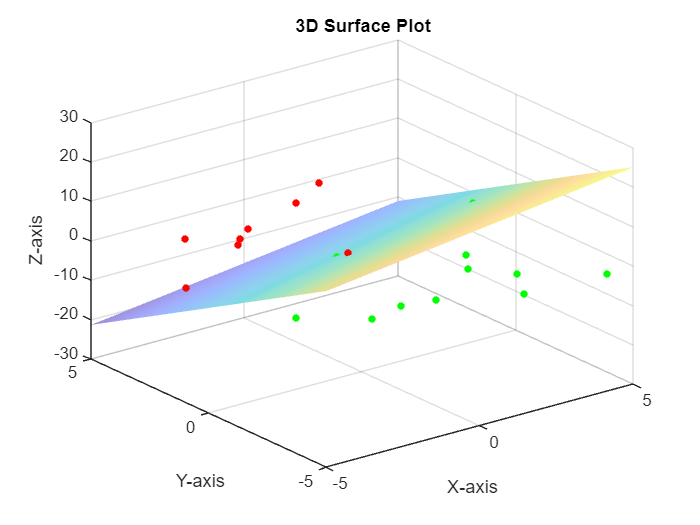

num_points = 20;

[x, y] = meshgrid(-5:0.1:5, -5:0.1:5);

z = -1 * (A*x + B*y + D) / C;

figure;
grid on;
xlim manual;
ylim manual;
surf(x, y, z);
shading interp;
alpha(0.5);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Surface Plot');
hold on;
for cycle_step = 1:num_points
    x = 10 * rand(1, 1) - 5;
    y = 10 * rand(1, 1) - 5;
    z = 10 * rand(1, 1) - 5;
    a = sim(net, [x; y; z]);
    if (a == 1)
        scatter3(x, y, z, 20, 'filled', 'r');
    else
        scatter3(x, y, z, 20, 'filled', 'g');
    end
end

Задание 3.

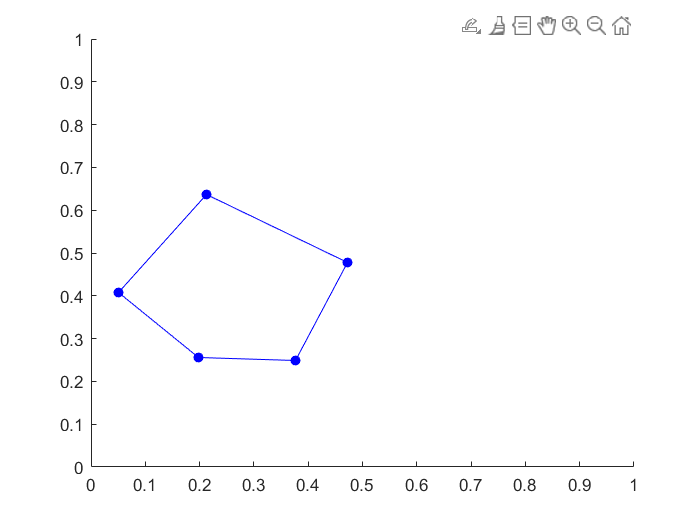

polygon_points = [];
points_amount = 5;
ginput_point_value = 1;
figure();
xlim manual;
ylim manual;
hold on;
for cycle_step = 1:points_amount
    [x_current, y_current] = ginput(ginput_point_value);
    scatter(x_current, y_current, 'filled', 'b');
    if (cycle_step ~= 1)
        x_values_for_line = [polygon_points(end, 1), x_current];
        y_values_for_line = [polygon_points(end, 2), y_current];
        line(x_values_for_line, y_values_for_line, 'Color', 'b')
    end
    polygon_points = [polygon_points; x_current y_current];
end
line([x_current, polygon_points(1, 1)], [y_current, polygon_points(1, 2)], 'Color', 'b');
hold off

polygon_points = [polygon_points; polygon_points(1, :)]

polygon_points =     0.0506    0.4077
    0.2127    0.6367
    0.4724    0.4778
    0.3766    0.2488
    0.1980    0.2558
    0.0506    0.4077


polygon_points = flip(polygon_points)

polygon_points =     0.0506    0.4077
    0.1980    0.2558
    0.3766    0.2488
    0.4724    0.4778
    0.2127    0.6367
    0.0506    0.4077


n = 5;

A = polygon_points(1:end - 1, 2) - polygon_points(2:end, 2)

A =     0.1519
    0.0070
   -0.2290
   -0.1589
    0.2290


B = polygon_points(2:end, 1) - polygon_points(1:end - 1, 1)

B =     0.1473
    0.1786
    0.0958
   -0.2597
   -0.1621


C = -1 * A .* polygon_points(1:end - 1, 1) -1 * B .* polygon_points(1:end - 1, 2)

C =    -0.0678
   -0.0471
    0.0624
    0.1991
    0.0545


W = zeros(n, 2);
W(:, 1) = A;
W(:, 2) = B;

net = newp([0 1; 0 1], n);
net.b{1} = C;
net.IW{1, 1} = W;

sim(net, [0.3; 0.4])

ans =      1
     1
     1
     1
     1


net1 = newp([0 1; 0 1; 0 1; 0 1; 0 1], 1);
net1.b{1} = - n;
net1.IW{1, 1} = ones(1, 5);

sim(net1, (sim(net, [0.3; 0.4])))

ans = 1

points_amount = 20;
ginput_point_value = 1;
figure();
grid on;
xlim manual;
ylim manual;
hold on;
scatter(polygon_points(:, 1), polygon_points(:, 2), 'filled', 'b');
line(polygon_points(:, 1), polygon_points(:, 2), 'Color', 'b')
for cycle_step = 1:points_amount
    [x_current, y_current] = ginput(ginput_point_value);
    a = sim(net1, (sim(net, [x_current; y_current])));
    if (all(a == 1))
        scatter(x_current, y_current, 'filled', 'r');
    else
        scatter(x_current, y_current, 'filled', 'g');
    end
end

a = 0

a = 0

a = 0

a = 1

a = 1

a = 1

a = 1

Error using ginput
Interrupted by figure deletion

Задание 4.

net = newp([-3 3; -3 3], 2);
p = [[1; 1] [1; 2]];
t = [[0; 0] [0; 0]];
net.adaptParam.passes = 1;
net = adapt(net, p, t);
a = sim(net, p)

p = [[2; -1] [2; 0]];
t = [[0; 1] [0; 1]];
net.adaptParam.passes = 1;
net = adapt(net, p, t);
a = sim(net, p)

p = [[-1; 2] [-2; 1]];
t = [[1; 0] [1; 0]];
net.adaptParam.passes = 1;
net = adapt(net, p, t);
a = sim(net, p)

p = [[-1; -1] [-2; -2]];
t = [[1; 1] [1; 1]];
net.adaptParam.passes = 1;
net = adapt(net, p, t);
a = sim(net, p)

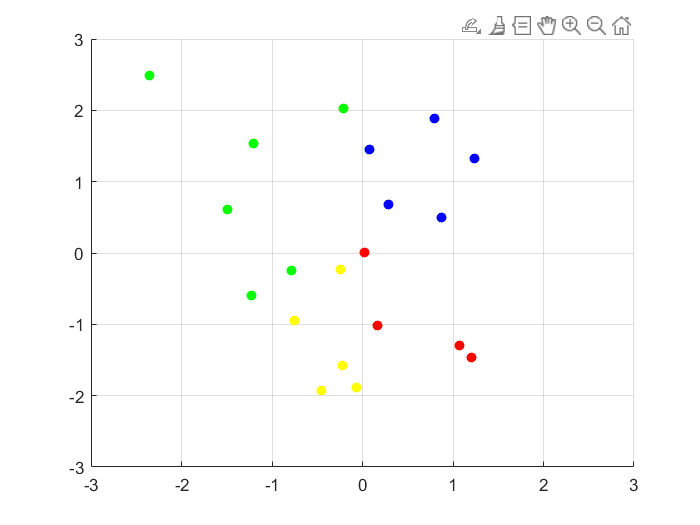

points_amount = 20;
ginput_point_value = 1;
figure();
grid on;
xlim manual;
ylim manual;
xlim([-3 3]);
ylim([-3 3]);
hold on;
for cycle_step = 1:points_amount
    [x_current, y_current] = ginput(ginput_point_value);
    a = sim(net, [x_current; y_current]);
    if (all(a == [0; 0]))
        scatter(x_current, y_current, 'filled', 'b');
    else 
        if (all(a == [0; 1]))
        scatter(x_current, y_current, 'filled', 'r');
        else 
            if (all(a == [1; 0]))
            scatter(x_current, y_current, 'filled', 'g');
            else
                scatter(x_current, y_current, 'filled', 'y');
            end
        end
    end
end

Задание 5.

preliminary_examination_number = 3;
N = 100;
lower_limit = 15;
total_threesold = 270;

net1 = newp([0 N; 0 N], 1);
net1.b{1} = -270;
net1.IW{1, 1} = [1 1 1];

net2 = newp([0 N], 1);
net2.b{1} = -15;
net1.IW{1, 1} = [1];

a = all(sim(net1, [100; 48; 55]), sim(net2, [100], sim))